% Luke McCubbin 
%Post compensation

clear all;

load('IQ_xItest')

npoints=length(xI_actual);  % Number of points
chip = 100e6;    % 100 MHz signal bandwidth
Fs = chip * 10;  % Sampling frequency

% Time vector
t = (0:npoints-1)/Fs;

sanityIn = xI_actual(1:30000); % Extract the data

sanityIn = sanityIn .* 10^(22.5/20); % Scale the values

power_avg_input = trapz(t, abs(sanityIn).^2) / ((t(end) - t(1))*100);  % Using numerical integration

power_input = 10 * log10(power_avg_input/1e-3);
fprintf('Matlab input data Average Power (dBm): %f dBm\n', power_input);

Matlab input data Average Power (dBm): 21.859690 dBm



%writematrix(sanityIn.', 'predist_22dBtest.csv'); % Transpose and save as CSV


load('memory_results.mat')
load('IQ_inputMem.mat')
load('IQ_outputMem.mat')
%load('IQout_5dB.csv')

% Parameters
npoints=length(xI_predict);  % Number of points


% Time vector
t = (0:npoints-1)/Fs;

sanityIn = MatlabInput(1:90001); % Extract the data

% sanityIn = sanityIn .* 10^(25.5/20); % Scale the values
% 
% writematrix(sanityIn.', 'Ideal25dB.csv'); % Transpose and save as CSV

sanityOut =MatlabOuttrain(1:90001);

%xI_actual = xI_predict.*10^(10/20);

figure(137)
[P_spec_predicted, F_spec_predicted] = spec_plot(xI_predict,1/Fs,135,'Memory effect predicted');

ACPR: -40.30


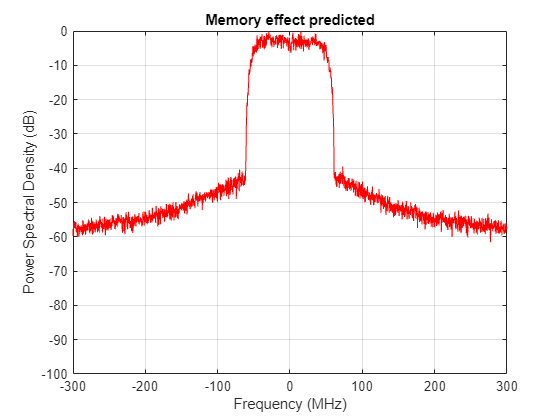

axis([-300 300 -100 0])

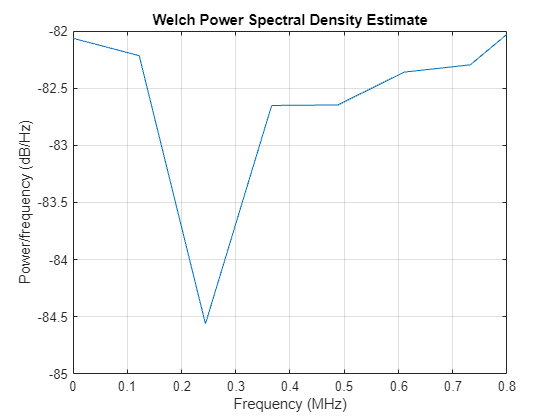

figure(1351)
pwelch(xI_predict,[],[],[],Fs)      %%% spectrum of output
xlim([0 0.8])


disp(sprintf('Baseband Predicted Peak-to-average ratio: %1.2f dB', 20*log10(max(abs(xI_predict))/rms(abs(xI_predict)))));

Baseband Predicted Peak-to-average ratio: 8.95 dB



PoutpkW=max(abs(xI_predict))^2/2/50;     %% peak output power in W
PredictedPoutpkdBm=10*log10(PoutpkW)+30     %%% peak output power in dBm

PredictedPoutpkdBm = 18.7683


power_avg_input = trapz(t, abs(xI_predict).^2) / ((t(end) - t(1))*100);  % Using numerical integration

power_input = 10 * log10(power_avg_input/1e-3);
fprintf('Predicted data Average Power (dBm): %f dBm\n', power_input);

Predicted data Average Power (dBm): 9.818139 dBm



figure(137)
[P_spec_input, F_spec_input] =spec_plot(sanityIn,1/Fs,135,'Input');

ACPR: -50.14


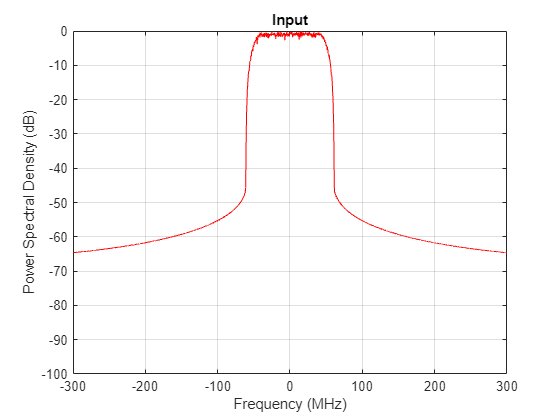

axis([-300 300 -100 0])

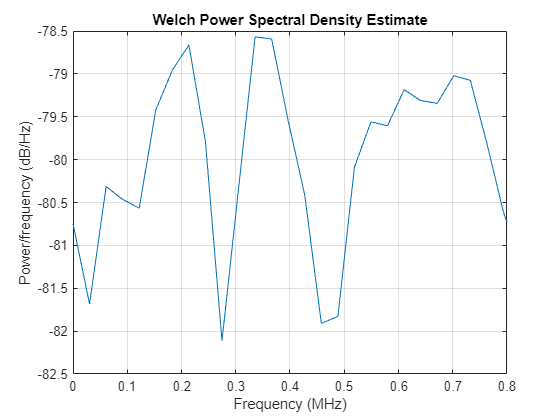

figure(1351)
pwelch(sanityIn,[],[],[],Fs)      %%% spectrum of output
xlim([0 0.8])


disp(sprintf('Baseband Input Peak-to-average ratio: %1.2f dB', 20*log10(max(abs(MatlabInput))/rms(abs(MatlabInput)))));

Baseband Input Peak-to-average ratio: 10.57 dB



PoutpkW=max(abs(MatlabInput))^2/2/50;     %% peak output power in W
InputPoutpkdBm=10*log10(PoutpkW)+30     %%% peak output power in dBm

InputPoutpkdBm = 20.5000


npoints2 = length(MatlabInput);

t2 = (0:npoints2-1)/Fs;

power_avg_input = trapz(t2, abs(sanityIn).^2) / ((t2(end) - t2(1))*100);  % Using numerical integration

power_input = 10 * log10(power_avg_input/1e-3);
fprintf('Matlab input data Average Power (dBm): %f dBm\n', power_input);

Matlab input data Average Power (dBm): 9.933337 dBm



figure(137)
[P_spec_output, F_spec_output] = spec_plot(sanityOut,1/Fs,135,'Output');

ACPR: -26.24


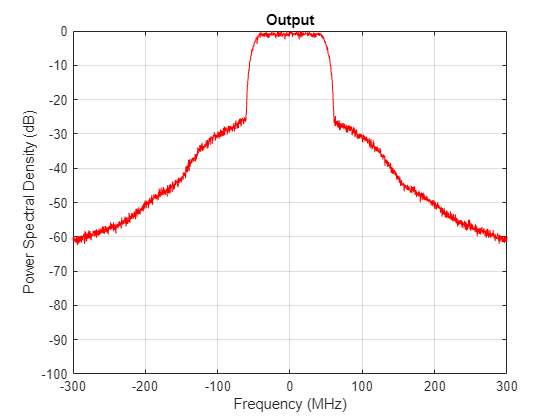

axis([-300 300 -100 0])

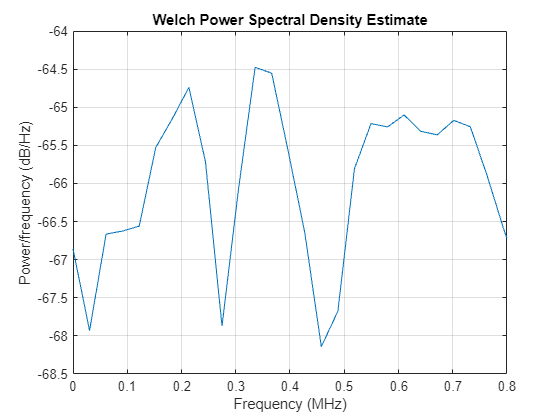

figure(1351)
pwelch(sanityOut,[],[],[],Fs)      %%% spectrum of output
xlim([0 0.8])


disp(sprintf('Baseband Matlab output Peak-to-average ratio: %1.2f dB', 20*log10(max(abs(sanityOut))/rms(abs(sanityOut)))));

Baseband Matlab output Peak-to-average ratio: 7.93 dB



PoutpkW=max(abs(sanityOut))^2/2/50;     %% peak output power in W
OutputPoutpkdBm=10*log10(PoutpkW)+30     %%% peak output power in dBm

OutputPoutpkdBm = 31.8168


npoints2 = length(sanityOut);

t2 = (0:npoints2-1)/Fs;

power_avg_input = trapz(t2, abs(sanityOut).^2) / ((t2(end) - t2(1))*100);  % Using numerical integration

power_input = 10 * log10(power_avg_input/1e-3);
fprintf('Matlab output data Average Power (dBm): %f dBm\n', power_input);

Matlab output data Average Power (dBm): 23.886443 dBm



N = length(xI_predict);

[pxx, f] = pwelch(xI_predict, hamming(1024), [], [], Fs, 'centered');

% Compute Occupied Bandwidth using the correct `freqrange`
BW_99 = obw(pxx, f);
fprintf('99%% Occupied Bandwidth (Welch): %.2f MHz\n', BW_99 / 1e6);

99% Occupied Bandwidth (Welch): 108.46 MHz



% Compute the RMSE
error_vector = sanityOut - sanityIn; % Difference between vectors
rmse = sqrt(mean(abs(error_vector).^2)); % Root Mean Square Error

% Normalize RMSE to calculate percentage error
rms_actual = sqrt(mean(abs(sanityOut).^2)); % RMS of the actual vector
rmse_percent = (rmse / rms_actual) * 100 % Percentage RMSE

rmse_percent = 101.9530


peak_actual = max(abs(sanityOut));
rmse_percent_peak = (rmse / peak_actual) * 100; % RMSE normalized by peak
fprintf('RMSE Percent output Error (Peak-Normalized): %.2f%%\n', rmse_percent_peak);

RMSE Percent output Error (Peak-Normalized): 40.92%



%load new xI_actual
load('Memory_out_test.mat')

xI_10dbtest = xI_actual .* 10^(10.5/20); % Scale the values
dB10_ideal = abs(xI_10dbtest);

% Compute the RMSE
error_vector = xI_predict - xI_10dbtest; % Difference between vectors
rmse = sqrt(mean(abs(error_vector).^2)); % Root Mean Square Error

% Normalize RMSE to calculate percentage error
rms_actual = sqrt(mean(abs(xI_predict).^2)); % RMS of the actual vector
rmse_percent = (rmse / rms_actual) * 100 % Percentage RMSE

rmse_percent = 14.2625


peak_actual = max(abs(xI_predict));
rmse_percent_peak = (rmse / peak_actual) * 100; % RMSE normalized by peak
fprintf('RMSE Percent NN Error (Peak-Normalized): %.2f%%\n', rmse_percent_peak);

RMSE Percent NN Error (Peak-Normalized): 5.09%


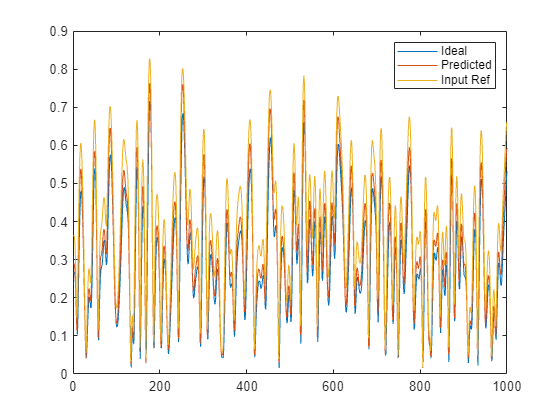




%Normalize signals
xI_input_norm = xI_10dbtest / max(abs(xI_10dbtest));
xI_predict_norm = xI_predict / max(abs(xI_predict));



%Trying to find inref for yout' signal:
inMag3 = abs(validate10dbout);
inPhase3 = angle(validate10dbout);
inRefMag3 = inMag3/6.02;
inRefAngle3 = inPhase3 + (76.2/180)*3.1416;

%this is wrong
%inRef = (inRefMag .* exp(1i * inRefAngle))/10^((Pinc)/20);
inRef3 = (inRefMag3 .* exp(1i * inRefAngle3));

yout_valid_norm = validate10dbout / max(abs(validate10dbout));

input_ref = abs(xI_input_norm(1:1000));
predicted = abs(yout_valid_norm(1:1000));
ideal = abs(xI_predict_norm(1:1000));


%save('envelopedata.mat', 'ideal', 'predicted', 'input_ref');

%save('SpecData.mat', 'F_spec_predicted', 'P_spec_predicted', 'F_spec_input','P_spec_input','F_spec_output', 'P_spec_output');

% figure(95)
plot(1:1000,abs(xI_input_norm(1:1000)),1:1000,abs(xI_predict_norm(1:1000)),1:1000,abs(yout_valid_norm(1:1000)))
legend('Ideal', 'Predicted','Input Ref')

% Compute the RMSE

error_vector = xI_predict_norm - xI_input_norm; % Difference between vectors
rmse = sqrt(mean(abs(error_vector).^2)); % Root Mean Square Error

% Normalize RMSE to calculate percentage error
rms_actual = sqrt(mean(abs(xI_predict_norm).^2)); % RMS of the actual vector
rmse_percent = (rmse / rms_actual) * 100 % Percentage RMSE

rmse_percent = 16.5025


peak_actual = max(abs(xI_predict_norm));
rmse_percent_peak = (rmse / peak_actual) * 100; % RMSE normalized by peak
fprintf('RMSE Percent NN predicted  (Peak-Normalized): %.2f%%\n', rmse_percent_peak);

RMSE Percent NN predicted  (Peak-Normalized): 5.89%



error_vector = yout_valid_norm - xI_input_norm; % Difference between vectors
rmse = sqrt(mean(abs(error_vector).^2)); % Root Mean Square Error

% Normalize RMSE to calculate percentage error
rms_actual = sqrt(mean(abs(yout_valid_norm).^2)); % RMS of the actual vector
rmse_percent = (rmse / rms_actual) * 100 % Percentage RMSE

rmse_percent = 125.9889


peak_actual = max(abs(yout_valid_norm));
rmse_percent_peak = (rmse / peak_actual) * 100; % RMSE normalized by peak
fprintf('RMSE Percent NN Output actual signal (Peak-Normalized): %.2f%%\n', rmse_percent_peak);

RMSE Percent NN Output actual signal (Peak-Normalized): 52.33%


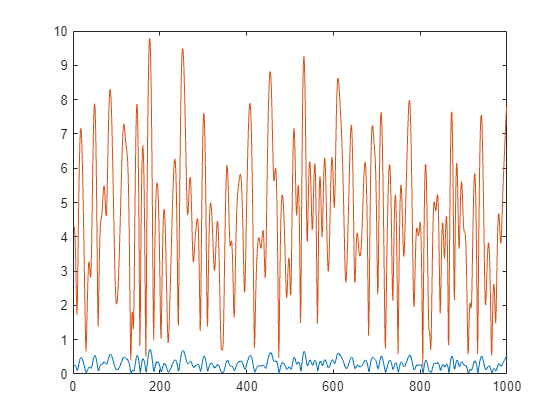

post_predict10dB = xI_predict;

load('predistRaw')

xI_predict7dB = xI_predict;
output_dist_10dB = sanityOut(1:30000);

sim25dBmOutNorm = yout_valid_norm / max(abs(yout_valid_norm));
plot(1:1000,abs(xI_input_norm(1:1000)),1:1000, abs(validate10dbout(1:1000)))

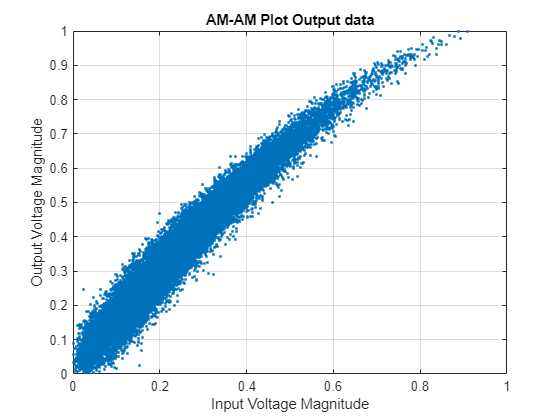


post_predict_norm = post_predict10dB / max(abs(post_predict10dB));

inputMag = abs(xI);
outputMag = abs(yout_valid_norm);
predictMag = abs(post_predict_norm);

figure;
plot(inputMag, outputMag, '.');
xlabel('Input Voltage Magnitude');
ylabel('Output Voltage Magnitude');
title('AM-AM Plot Output data');
grid on;

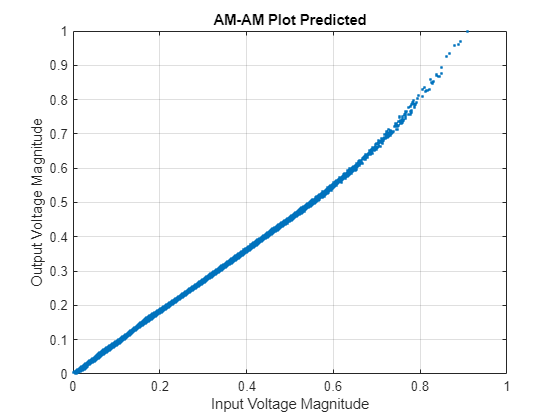


figure;
plot(inputMag, predictMag, '.');
xlabel('Input Voltage Magnitude');
ylabel('Output Voltage Magnitude');
title('AM-AM Plot Predicted');
grid on;



figure(137)
spec_plot(validate10dbout,1/Fs,135,'Output');

ACPR: -26.34


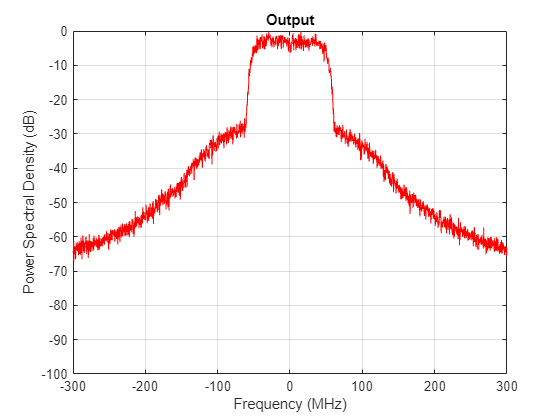

axis([-300 300 -100 0])

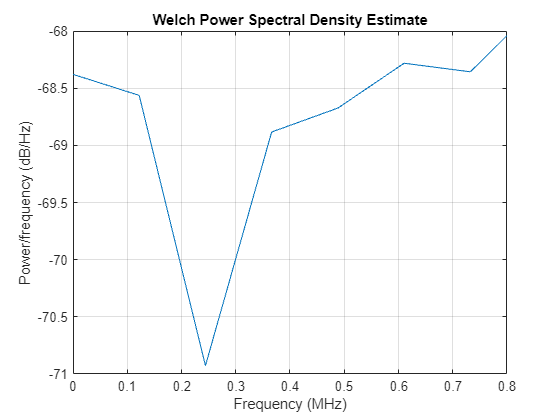

figure(1351)
pwelch(validate10dbout,[],[],[],Fs)      %%% spectrum of output
xlim([0 0.8])





save('SingnalsRaw2.mat', 'validate10dbout')

% Define time range
t_start = 0;           % Start time in seconds
t_end = 30e-6;         % End time in seconds (30 microseconds)

% Generate linearly spaced time vector
time = linspace(t_start, t_end, 30000);

% Display basic info
disp(['Time vector size: ', num2str(size(time))]);

Time vector size: 1  30000


disp(['First time value: ', num2str(time(1)), ' s']);

First time value: 0 s


disp(['Last time value: ', num2str(time(end)), ' s']);

Last time value: 3e-05 s





save('Sim10dbmVinVout.mat', 'time', 'xI_predict7dB', 'output_dist_7dB', 'output_predist_7dB', 'post_predict10dB', 'output_dist_10dB')